clear
clc
digits(6)

I = 1; % [A]
sigma = 1; % [A/V]

source = [0; 1]';
sink = [0; -1]';

syms r a b c d x y theta
syms phi(x,y) psi(x,y) Phi(x,y) Psi(x,y)
F(r) = a + b * log(r) + c * r^2 + d * r^2 * log(r);

phi(r,theta) = simplify(1/r * diff(r * diff(F(r),r),r));
phi(x,y) = subs(phi(r,theta),r,sqrt(x^2+y^2));
phi(x,y) = subs(phi(x,y),c,-d);
phi(x,y) = vpa(subs(phi(x,y),d,-I/(2*pi)/sigma/4));

psi(x,y) = vpa(simplify(int(diff(phi(x,y),y),x)));
psi(x,y) = str2sym(replace(replace(string(psi),"atan","atan2"),'/',','));

Phi(x,y) = 0;
Psi(x,y) = 0;
for i = 1:size(source,1)
   Phi(x,y) = Phi(x,y) + (phi(x-source(i,1),y-source(i,2)));
   Psi(x,y) = Psi(x,y) + (psi(x-source(i,1),y-source(i,2)));
end
for i = 1:size(sink,1)
   Phi(x,y) = Phi(x,y) + (phi(x-sink(i,1),y-sink(i,2)));
   Psi(x,y) = Psi(x,y) + (psi(x-sink(i,1),y-sink(i,2)));
end

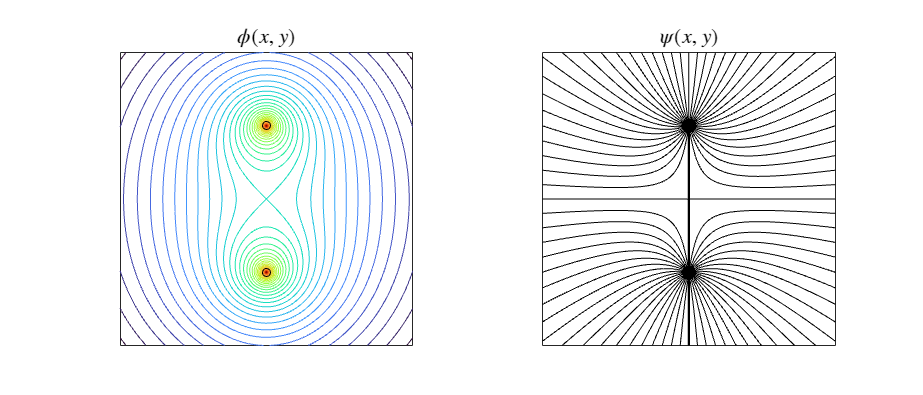

figure("Position",[0,0,1400,600])
tiledlayout(1,2)
nexttile()
fc_phi = fcontour(Phi, ...
    'MeshDensity',400, ...
    'Fill',"off");
fc_phi.LevelList = -1:0.025:1;
hold on

scatter(source(:,1),source(:,2),16,'ko');
scatter(sink(:,1),sink(:,2),16,'ko');
hold off

xlim([-2 2]);
ylim([-2,2]);
axis equal
xticks(-10); yticks(-10);
box on
title("$\phi(x,y)$","Interpreter","latex")
colormap(turbo());

nexttile()
fc_psi = fcontour(Psi,'k', ...
    'MeshDensity',200, ...
    'LineWidth',0.5);
fc_psi.LevelList = -1:0.025:1;
hold on

scatter(source(:,1),source(:,2),16,'ko');
scatter(sink(:,1),sink(:,2),16,'ko');
hold off

xlim([-2,2]);
ylim([-2,2]);
axis equal
xticks(-10); yticks(-10);
box on
title('$\psi(x,y)$',"Interpreter","latex")